# E9

#### Reconeixement

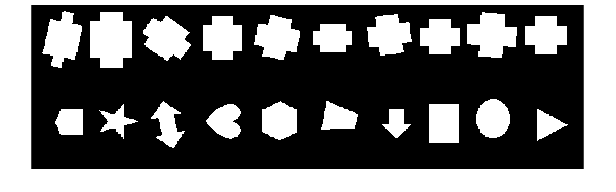

BW = rgb2gray(imread("creus_no_creus.png")) < 200;
imshow(BW);

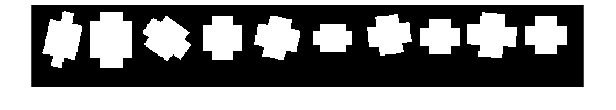


BWU = BW(1:end/2, :);
imshow(BWU);

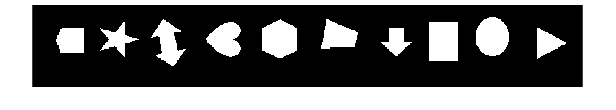

BWD = BW(end/2:end, :); 
imshow(BWD);


CCU = bwconncomp(BWU);
CCD = bwconncomp(BWD);

propsU = regionprops('table', CCU, 'Perimeter', 'Centroid', 'BoundingBox', 'Solidity', 'Circularity', 'Extent', 'MinorAxisLength', 'MajorAxisLength', 'MinFeretProperties', 'MaxFeretProperties');

propsD = regionprops('table', CCD, 'Perimeter', 'Centroid', 'BoundingBox', 'Solidity', 'Circularity', 'Extent', 'MinorAxisLength', 'MajorAxisLength', 'MinFeretProperties', 'MaxFeretProperties');

NumObj = CCU.NumObjects;
FU = [propsU.Perimeter./propsU.MinFeretDiameter, propsU.Circularity, propsU.Solidity, propsU.Extent, propsU.MinorAxisLength./propsU.MajorAxisLength, propsU.MinFeretDiameter./propsU.MaxFeretDiameter, ones(1, 10)'];
FD = [propsD.Perimeter./propsD.MinFeretDiameter, propsD.Circularity, propsD.Solidity, propsD.Extent, propsD.MinorAxisLength./propsD.MajorAxisLength, propsD.MinFeretDiameter./propsD.MaxFeretDiameter, zeros(1, 10)'];

Features = [FU;FD];
Output = false([2*NumObj,1]);
Output(1:NumObj) = true;
xnew = FU(1,:)

xnew =     5.5554    0.4791    0.8428    0.6136    0.6697    0.5939    1.0000


ynew = trainedModel.predictFcn(xnew(1:end-1))

ynew = 1